# DeepInterpolation - Tiny Ophys Inference Example

This example imports and uses a pre-trained DeepInterpolation model in MATLAB for inferring tiny ophys sample data.

## Run setup for initialization of path

base_folder = setup;

## Import and Assemble Model

The pre-trained network is available on an external file storage, as it is a bit larger (120 MB) than the other example networks. It is automatically downloaded here.

trained_model_file = '2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5';
if ~isfile(fullfile(base_folder, 'sampleData', trained_model_file))
    dropboxFileURL = 'https://www.dropbox.com/sh/vwxf1uq2j60uj9o/AAC0sZWahCJFBRARoYsw8Nnra/2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5?dl=1';
    destinationFile = fullfile(base_folder, 'sample_data',trained_model_file);
    try
        disp('Downloading trained model...');
        websave(destinationFile, dropboxFileURL);
        disp('Downloaded the trained model successfully.');
    catch ex
        disp('Error downloading the trained model.');
        throw(ex);
    end
else
    disp('Found the trained model')
end

Downloaded the trained model successfully.


Then import the trained model:

importednet = importKerasLayers('2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5','ImportWeights',true);

Placeholders layers were added.  We'll replace the output with an [`maeRegressionLayer`](https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html) from the documentation to make predictions.

placeholders = findPlaceholderLayers(importednet);
disp(placeholders)

  PlaceholderOutputLayer with properties:

            Name: 'conv2d_10_OutputLayer_PLACEHOLDER'
     InputLabels: {''}
    OutputLabels: {''}
   Learnable Parameters
    No properties.
   State Parameters
    No properties.
  Show all properties


regressionnet = replaceLayer(importednet, placeholders.Name , maeRegressionLayer);
deepinterpnet = assembleNetwork(regressionnet)

deepinterpnet =   DAGNetwork with properties:

         Layers: [33×1 nnet.cnn.layer.Layer]
    Connections: [36×2 table]
     InputNames: {'input_1'}
    OutputNames: {'MAE Regression'}

## Analyze Network

Optionally analyze the network

if false
    analyzeNetwork(deepinterpnet)
end

## Import Sample TIFF Volume

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));

## **Choose the number of frames to be omitted before and after the predicted frame**

pre_post_omission = ceil(0); 

## **Choose which frame to predict**

target_frame = ceil(60); 

## Pre-processing before DeepInterpolation

The network expects an input of size:

inputSize = regressionnet.Layers(1).InputSize

inputSize =    512   512    60


The size of the *ophys* image is:

size(ophys)

ans =    512   512   100


Make prediction with the equivalent sized input:

pre_frame = 30; % Fixed number of frames before the predicted frame
post_frame = 30; % Fixed number of frames after the predicted frame

### Drop the omitted frames before prediction

input_index = (target_frame - pre_frame - pre_post_omission) : (target_frame + post_frame + pre_post_omission );
  
pre_post_omission_index = target_frame-pre_post_omission : target_frame+pre_post_omission; % index of frames to be dropped

for drop_frame = pre_post_omission_index
    input_index = input_index(input_index ~= drop_frame); % drop the predicted frame and the frames omitted before and after the predicted frame
end

### Normalization of frames

[ophys, C, S] = normalize(ophys,3,"center","mean","scale","std"); % where C = mean, S = std

## **Perform DeepInterpolation**

try
    ophysinterp = predict(deepinterpnet, ophys(:,:,input_index));
catch
    warning('Problem using predict.  Returning null.');
    ophysinterp = [];
end

## Rescale normalized frames

ophys  = (ophys .* S)+C;
ophysinterp = (ophysinterp .* S)+C;

## Plot input movie

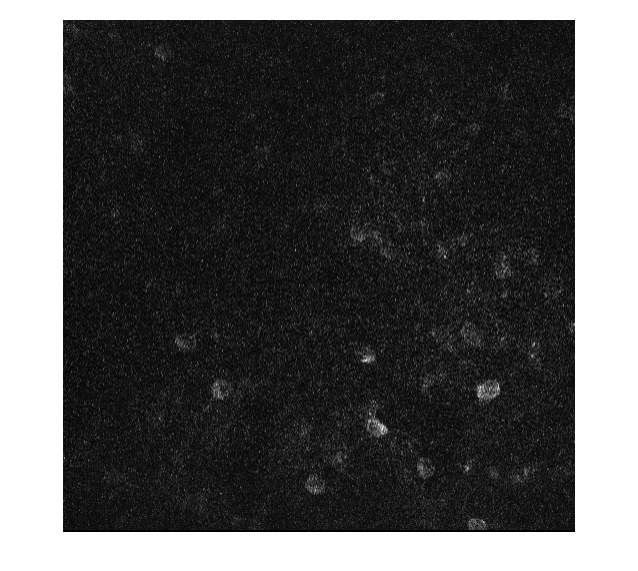

figure;
for idx = input_index
    imshow(ophys(:,:,idx), [])
    pause(0.5)
end
title("Input Frames")

## Plot DeepInterpolation Result

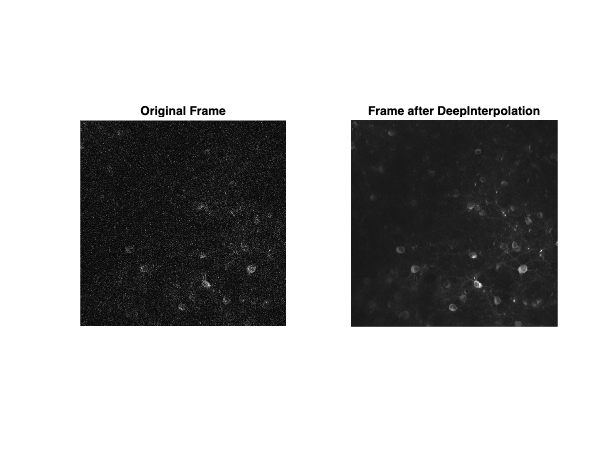

f = figure();
title("DeepInterpolation of tiny ophys data")
f.WindowState = 'maximized';
subplot(1,2,1)
imshow(ophys(:,:,target_frame),[])
title("Original Frame")
subplot(1,2,2)
imshow(ophysinterp, [])
title("Frame after DeepInterpolation")